We work directly in $V=\text{span}\bigl\{1+x^2,1-x^2,\sqrt{x}\bigr\}$. Notice that $V$ is a 3-dimensional substpace of  $C([0,1])$ and $S=\text{span}\bigl\{1+x^2,1-x^2\bigr\}$is a two dimensional subspace of $V$and that in $V$ we are projecting the vector $\sqrt{x}$ onto $S.$

Next we approximate the same calculation in a discretized version with $N$ points along each function, so working in $\mathbb R^N$. 

Finally, we redo the computation exactly using the basis representation of elements of $S$ and the corresponding matrix representation of the inner product there.

syms x;
f1 = 1 + x^2;
f2 = 1 - x^2;
f3 = x^(1/2);

%The following is a quick Gram-Schmidt on {f1,f2}
g1 = f1/sqrt(int(f1*f1,x,0,1))

$$g1 = \frac{\sqrt{7}\,\sqrt{15}\,\left(x^{2}+1\right)}{14}$$

g2 = f2 - int(g1*f2,x,0,1)*g1

$$g2 = 1-\frac{\sqrt{7}\,\sqrt{15}\,\sqrt{105}\,\left(x^{2}+1\right)}{245}-x^{2}$$

g2 = g2/sqrt(int(g2*g2,x,0,1))

$$g2 = -\frac{\sqrt{21}\,\left(x^{2}+\frac{\sqrt{7}\,\sqrt{15}\,\sqrt{105}\,\left(x^{2}+1\right)}{245}-1\right)}{2}$$

d1 = int(f3*g1,0,1), double(d1)

$$d1 = \frac{10\,\sqrt{105}}{147}$$

ans = 0.6971

d2 = int(f3*g2,0,1), double(d2)

$$d2 = -\frac{2\,\sqrt{21}}{147}$$

ans = -0.0623


%Compute the projection
f3hat = d1*g1 + d2*g2

$$f3hat = \frac{x^{2}}{7}+\frac{4\,\sqrt{7}\,\sqrt{15}\,\sqrt{105}\,\left(x^{2}+1\right)}{735}-\frac{1}{7}$$

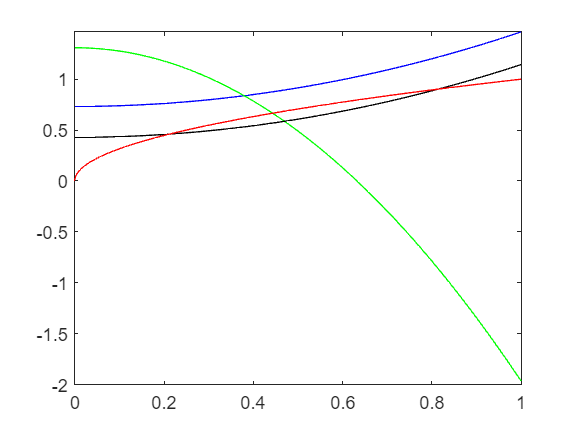


%Plot everything
fig2 = figure(2);
fplot(g1,[0 1],"b")
hold on;
fplot(g2, [0 1], "g")
fplot(f3hat, [0 1],"k")
fplot(f3, [0 1],"r")

Now let's discretize the problem. Note here that we use the standard inner product scaled by $1/N$ in $\mathbb R^N$.

N = 30;
xs = linspace(0,1,N)';
u1s = 1 + xs.^2;
u2s = 1 - xs.^2;
bs = xs.^(1/2);

%Quick Gram-Schmidt
u1s = u1s/norm(u1s, 1/N*eye(N));
u2s = u2s - ip(u1s, u2s, 1/N*eye(N))*u1s;
u2s = u2s/norm(u2s, 1/N*eye(N));

c1 = ip(bs,u1s,1/N*eye(N))

c1 = 0.6935

ans = 0.6935

c2 = ip(bs,u2s,1/N*eye(N))

c2 = -0.0704

ans = -0.0704

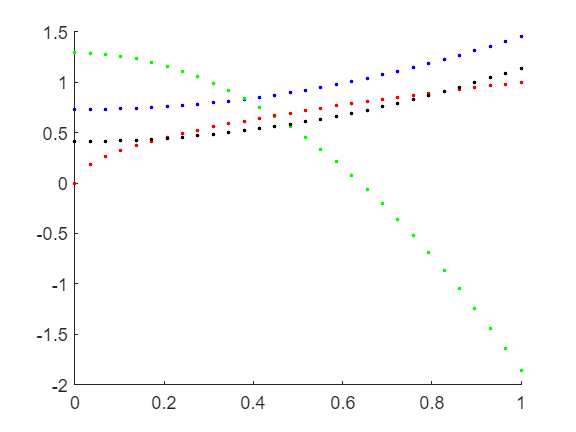


bshat = c1*u1s + c2*u2s;


fig1 = figure(1);
clf(fig1);
scatter(xs,u1s,".b")
hold on;
scatter(xs, u2s, ".g")
scatter(xs, bs, ".r")
scatter(xs, bshat, ".k")
hold off;

Here finally we convert the exact computation into a matrix based computation using representations. $F$ will be the matrix (positive-definite and symmetric) of inner products among the basis elements. Notice $F$is $3\times 3$ and the inner product on $\mathbb R^3$ used here is


$$\langle u,v\rangle=v^TFu$$


Note above that $\text{f3hat}$ 


$$\frac{\sqrt{5}\sqrt{15}\sqrt{105}}{735}=\frac{1}{7}$$


So 


$$\text{f3hat}=\frac{x^2}{7}+\frac{4}{7}(1+x^2)-\frac{1}{7}=\frac{3}{7}+\frac{5}{7}x^2$$


a11 = int(f1*f1,0,1);
a22 = int(f2*f2,0,1);
a33 = int(f3*f3,0,1);
a12 = int(f1*f2,0,1);
a13 = int(f1*f3,0,1);
a23 = int(f2*f3,0,1);
F = [a11 a12 a13
     a12 a22 a23
     a13 a23 a33];


v1 = [1 0 0]'; % 1 + x^2
v2 = [0 1 0]'; % 1 - x^2
b = [0 0 1]'; % sqrt(x)

%Quic Gram-Schmidt using the inner product on R^3 <u, v>_F = v^TFu
u1p = v1;
u1 = u1p/norm(u1p, F)

$$u1 = \left(\begin{array}{c} \frac{\sqrt{7}\,\sqrt{15}}{14}\\ 0\\ 0 \end{array}\right)$$

u2p = v2 - ip(v2,u1,F)*u1;
u2 = u2p/norm(u2p, F)

$$u2 = \left(\begin{array}{c} -\frac{3\,\sqrt{21}}{14}\\ \frac{\sqrt{21}}{2}\\ 0 \end{array}\right)$$

b1 = ip(b,u1,F)

$$b1 = \frac{10\,\sqrt{7}\,\sqrt{15}}{147}$$

double(b1)

ans = 0.6971

b2 = ip(b,u2,F)

$$b2 = -\frac{2\,\sqrt{21}}{147}$$

double(b2)

ans = -0.0623

bhat = b1*u1 + b2*u2

$$bhat = \left(\begin{array}{c} \frac{4}{7}\\ -\frac{1}{7}\\ 0 \end{array}\right)$$

fhat = [1+x^2 1-x^2 sqrt(x)]*bhat

$$fhat = \frac{5\,x^{2}}{7}+\frac{3}{7}$$

function t = ip(u,v, A)
    t = v'*A*u;
end

function n = norm(v, A)
    n = sqrt(ip(v,v,A));
end
